# Shocktube Calculator with Automatic Differentiation

clear
clc


Initialize vector of values we want to take the gradient with respect to. Here we will use gamma and the initial interface location.


A = AutoDiff([1.4 7]);

gamma = A(1,1);
mu = 5e-1;
K = 5e-1;

tf = 150;



xs0 = 2; %Shock location
xi0 = A(1,2); %Interface location

ls0 = 0.0001; %Shock width
li0 = 0.1; %Interface width
x = linspace(0,9,50)';

ss = 0.5*erfc((x-xs0)/ls0);

ss2 = 3 + (1 - 3)*0.5*erfc((x-xi0)/li0);

dx = 4*0.5;

rho = 0.125 + (1.3 - 0.125)*ss;

rho = rho.*ss2;

U = 0*rho;
P = 0.1 + (1.3 - 0.1)*ss;

E = P./(gamma-1) + 0.5*rho.*U.^2;

y0 = [rho rho.*U E];

Run 4th order Runge-Kutta with 5th order adaptive time stepping.

tic
[tf, yf] = ODE.rkf45(@(t,y) ODE.test.NS_1D_RHS(t,y,mu,K,gamma,dx), y0, 0, tf, 0.001,1e-6,A);
toc

Elapsed time is 70.274869 seconds.


Extract values and gradients.

yfv=[];
dyfv = [];

for i = 1:length(tf)
    %yfv(:,:,i) = yf{i};
    yfv(:,:,i) = getvalue(yf{i});
    dyfv(:,:,:,i) = reshape(full(getderivs(yf{i})),[size(squeeze(yfv(:,:,i))) size(A,2)]);
end

Plot density, velocity and energy XT diagrams and density gradient XT diagram.

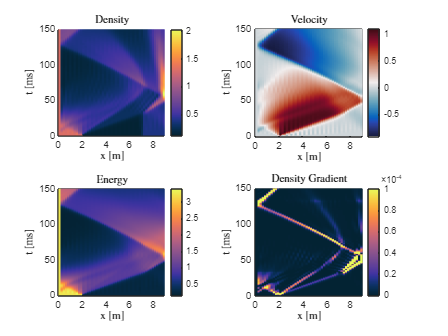

figure
subplot(2,2,1)
pcolor(x,tf,squeeze(yfv(:,1,:))')
shading flat
utils.cmocean('thermal')
colorbar
axis square
title('Density','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,2,2)
pcolor(x,tf,squeeze(yfv(:,2,:))'./squeeze(yfv(:,1,:))')
shading flat
utils.cmocean('balance')
colorbar
axis square
title('Velocity','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,2,3)
pcolor(x,tf,squeeze(yfv(:,3,:))')
shading flat
utils.cmocean('thermal')
colorbar
axis square
title('Energy','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,2,4)
pcolor(x,tf,utils.Grad(squeeze(yfv(:,1,:))',dx).^2)
shading flat
utils.cmocean('thermal')
colorbar
caxis([0 0.0001])
axis square
title('Density Gradient','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

Plot XT diagrams of the gradient of the density, momentum and energy with respect to both gamma and the interface initial location.

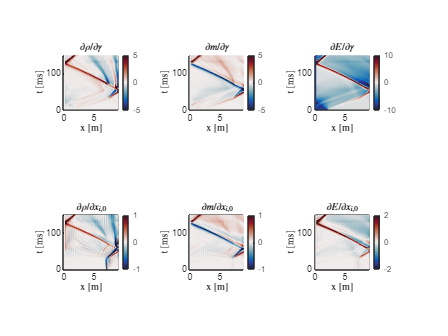

figure
subplot(2,3,1)
pcolor(x,tf,squeeze(dyfv(:,1,1,:))')
shading flat
utils.cmocean('balance')
colorbar
caxis([-5 5])
axis square
title('$\partial \rho / \partial \gamma$','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,3,2)
pcolor(x,tf,squeeze(dyfv(:,2,1,:))')
shading flat
utils.cmocean('balance')
colorbar
caxis([-5 5])
axis square
title('$\partial m / \partial \gamma$','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,3,3)
pcolor(x,tf,squeeze(dyfv(:,3,1,:))')
shading flat
utils.cmocean('balance')
colorbar
caxis([-10 10])
axis square
title('$\partial E / \partial \gamma$','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,3,4)
pcolor(x,tf,squeeze(dyfv(:,1,2,:))')
shading flat
utils.cmocean('balance')
colorbar
caxis([-1 1])
axis square
title('$\partial \rho / \partial x_{i,0}$','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,3,5)
pcolor(x,tf,squeeze(dyfv(:,2,2,:))')
shading flat
utils.cmocean('balance')
colorbar
caxis([-1 1])
axis square
title('$\partial m / \partial x_{i,0}$','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')

subplot(2,3,6)
pcolor(x,tf,squeeze(dyfv(:,3,2,:))')
shading flat
utils.cmocean('balance')
colorbar
caxis([-2 2])
axis square
title('$\partial E / \partial x_{i,0}$','Interpreter','latex')
xlabel('x [m]','Interpreter','latex')
ylabel('t [ms]','Interpreter','latex')